### Load and store image

% Location 
path = '/Users/kmp/Desktop/Com-aid final project';
% Store the output 
imageFolder = fullfile(path,'Dataset');
imds = imageDatastore(imageFolder, 'LabelSource', 'foldernames', 'IncludeSubfolders',true);

recheck images and label of each category 

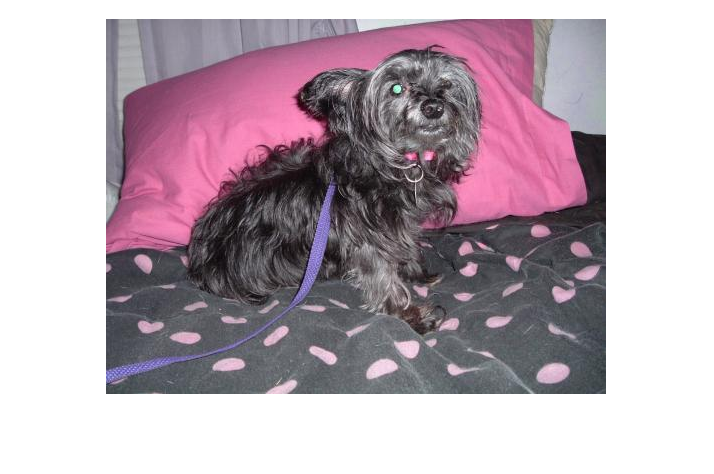

% Find the first instance of an image for each category
Dog = find(imds.Labels == 'Dog', 1);
Cat = find(imds.Labels == 'Cat', 1);
NotCatorDog=find(imds.Labels=='NotCatorDog',1);
figure
imshow(readimage(imds,Dog))

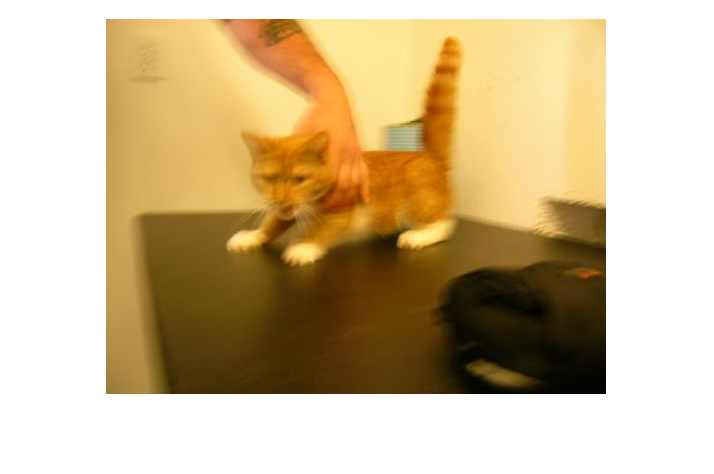

imshow(readimage(imds,Cat))

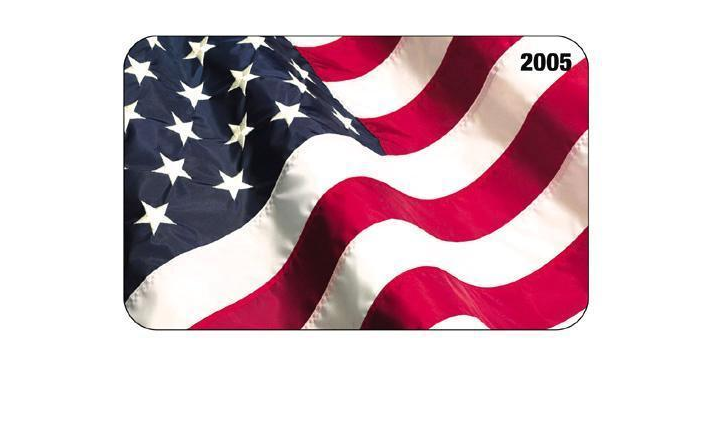

imshow(readimage(imds,NotCatorDog))

Set number of each label to be equal(800)

% count each label
tbl = countEachLabel(imds)

tbl = 3×2 table
       Label       Count
    ___________    _____

    Cat             989 
    Dog             990 
    NotCatorDog    1088 


% Determine the smallest amount of images in a category
minSetCount = min(tbl{:,2}); 
% Limit the number of images to reduce the time it takes
% run this example.
maxNumImages = 800;
minSetCount = min(maxNumImages,minSetCount);

% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');

% Notice that each set now has exactly the same number of images.
countEachLabel(imds)

ans = 3×2 table
       Label       Count
    ___________    _____

    Cat             800 
    Dog             800 
    NotCatorDog     800 


###  Divide data into training and validation data set

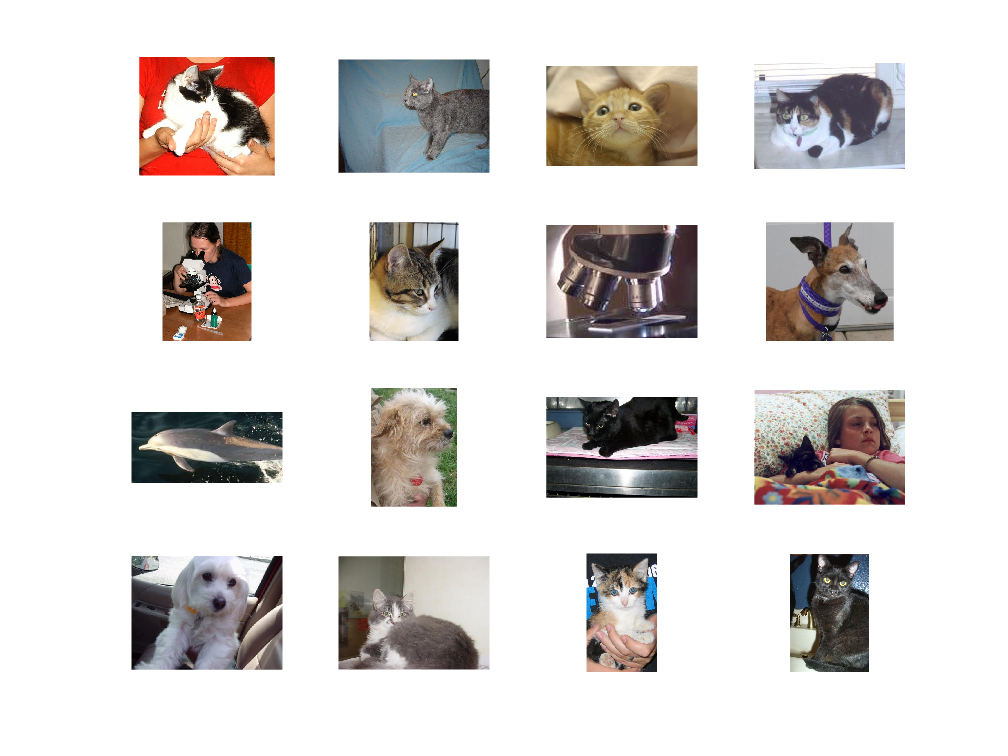

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.8,'randomized');
% Display some sample images.
numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

% set number of classes
numClasses = numel(categories(imdsTrain.Labels))

numClasses = 3

### **Load Pretrained Network**

# resnet50

net1=resnet50;
net1.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'input_1'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


inputSize = net1.Layers(1).InputSize

inputSize =    224   224     3


### **Replace Final Layers**

lgraph1 = layerGraph(net1);
[learnableLayer,classLayer] = findLayersToReplace(lgraph1);
[learnableLayer,classLayer]

ans =   1×2 Layer array with layers:

     1   'fc1000'                       Fully Connected         1000 fully connected layer
     2   'ClassificationLayer_fc1000'   Classification Output   crossentropyex with 'tench' and 999 other classes


if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end
lgraph1 = replaceLayer(lgraph1,learnableLayer.Name,newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph1 = replaceLayer(lgraph1,classLayer.Name,newClassLayer);
layers = lgraph1.Layers;
connections = lgraph1.Connections;
layers(1:10) = freezeWeights(layers(1:10));
lgraph1 = createLgraphUsingConnections(layers,connections);

### Train Network

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain, ...
    'DataAugmentation', imageAugmenter,'ColorPreprocessing','gray2rgb');
augimdsValidation = augmentedImageDatastore(inputSize,imdsValidation,"ColorPreprocessing","gray2rgb");
miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');
classNames = net1.Layers(end).ClassNames;

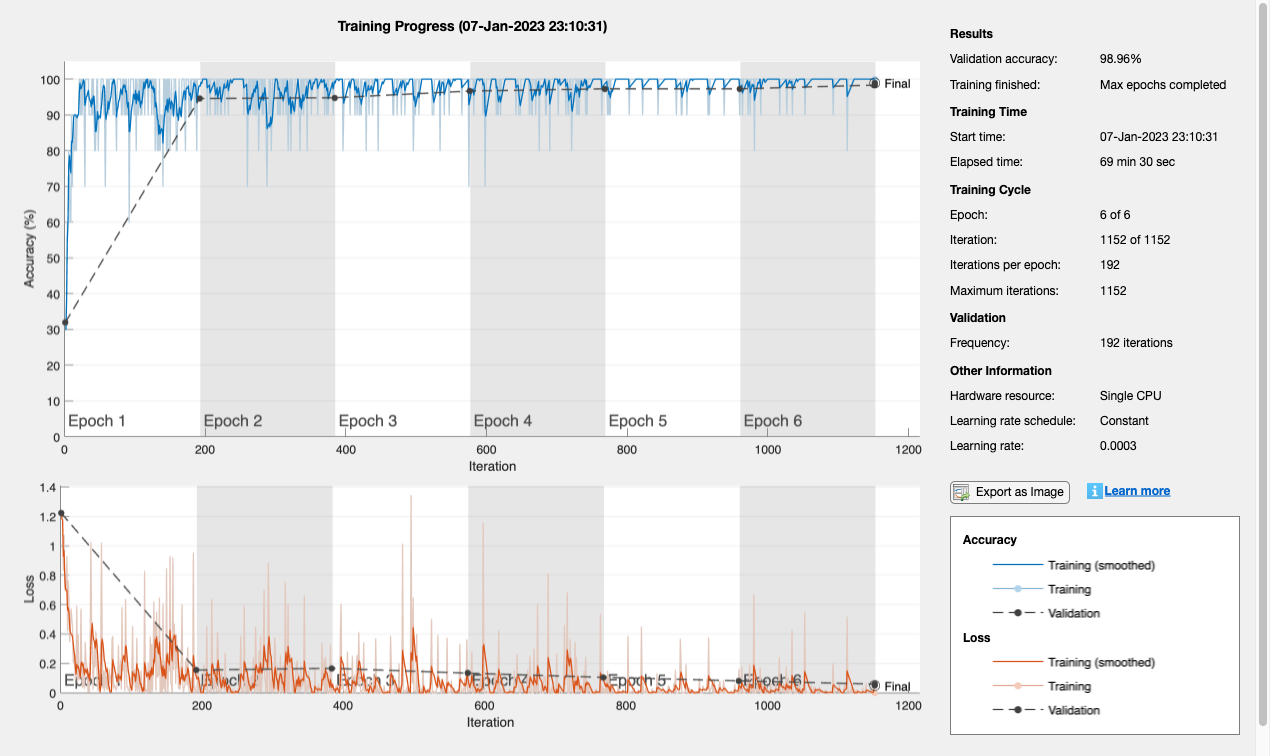

% train Renet50 
nettrain = trainNetwork(augimdsTrain,lgraph1,options);

Save network

save nettrain

Classify test set images

[YPrednet1,scoresnet1] = classify(nettrain,augimdsValidation);

Display four sample validation images and their labels

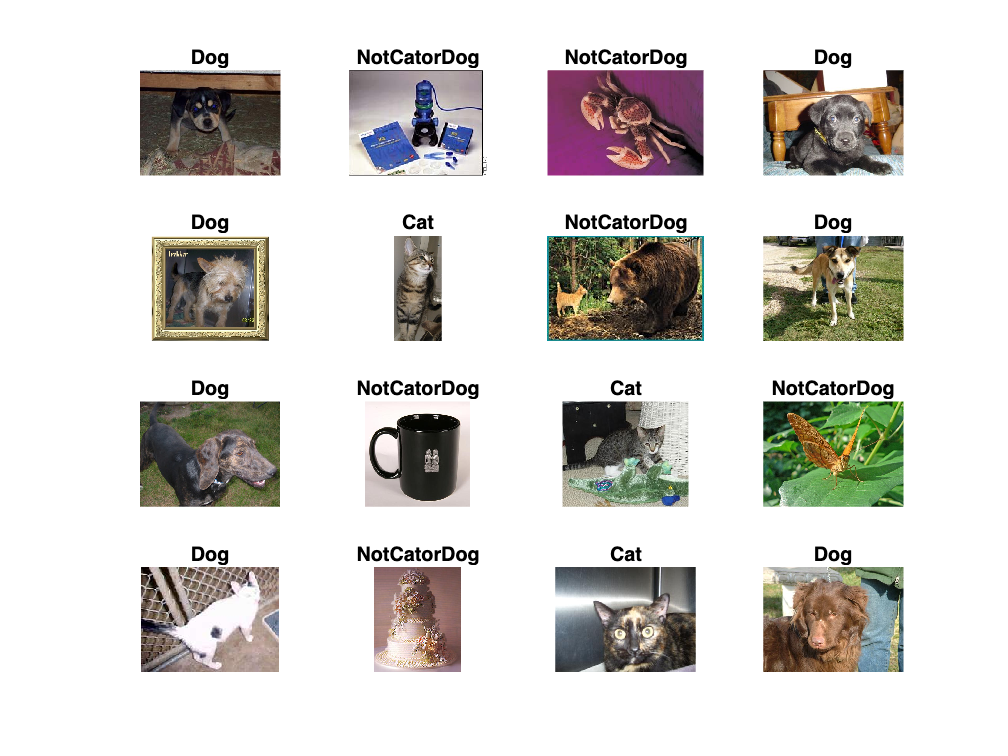

r = randperm(augimdsValidation.NumObservations,16);
for i = 1:numel(r)
    subplot(4,4,i)
    I = readimage(imdsValidation,r(i));
    label1 = YPrednet1(r(i));
    imshow(I)
    title(label1)
end

Calculate accuracy

YValidationnet1= imdsValidation.Labels;
accuracy1 = mean(YPrednet1 == YValidationnet1)

accuracy1 = 0.9896

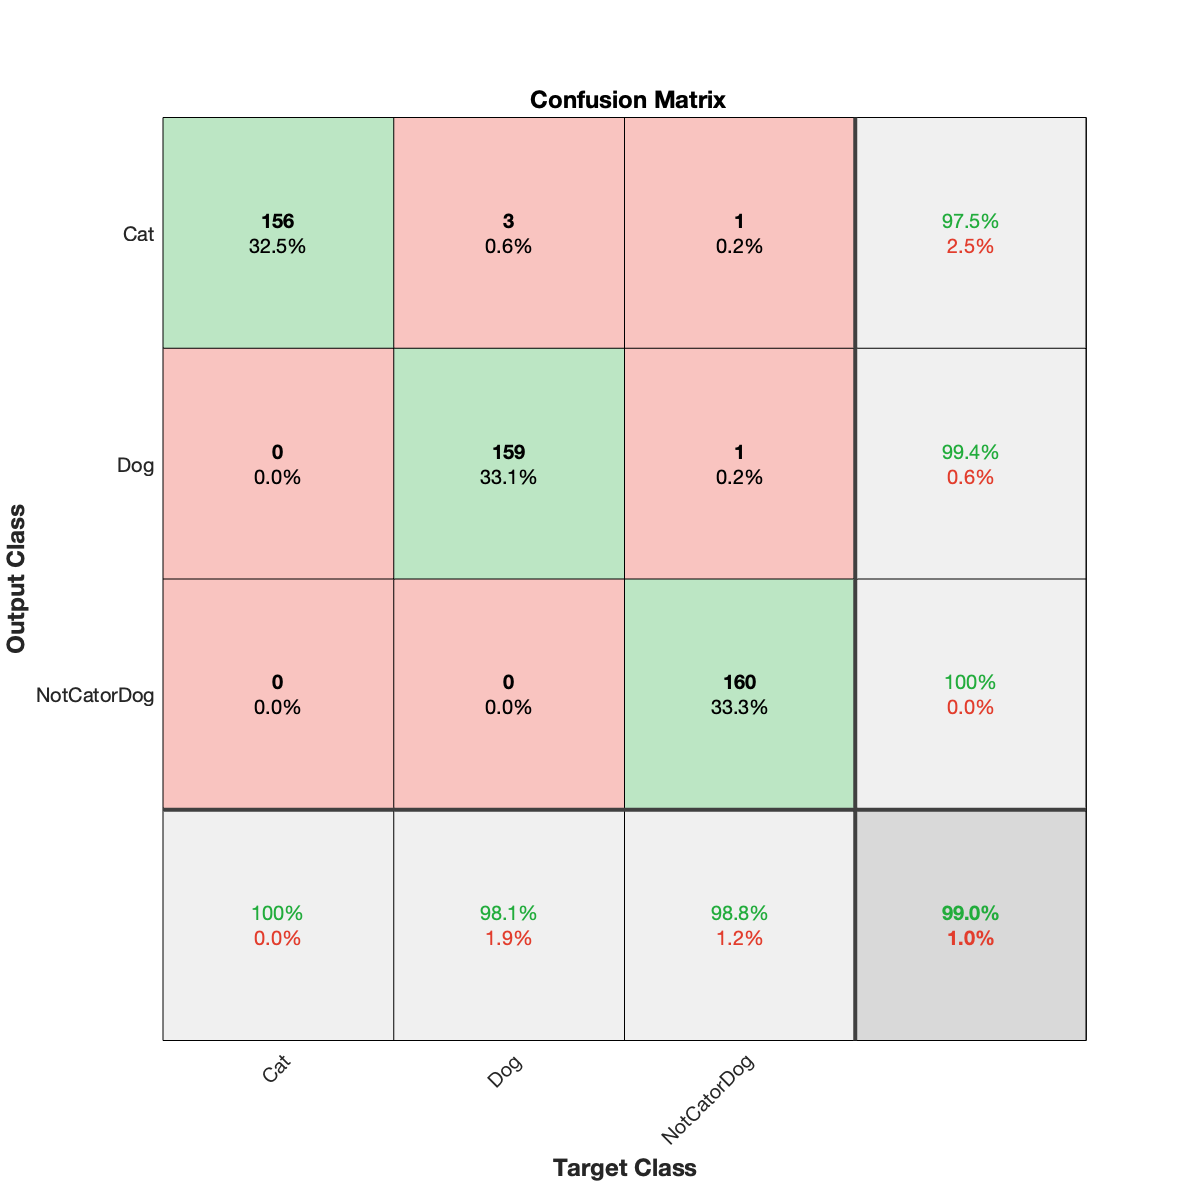

plotconfusion(YPrednet1,YValidationnet1)

### Googlelanet

net2=googlenet;
net2.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


### **Replace Final Layers**

lgraph2 = layerGraph(net2);
[learnableLayer,classLayer] = findLayersToReplace(lgraph2);
[learnableLayer,classLayer]

ans =   1×2 Layer array with layers:

     1   'loss3-classifier'   Fully Connected         1000 fully connected layer
     2   'output'             Classification Output   crossentropyex with 'tench' and 999 other classes

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end
lgraph2 = replaceLayer(lgraph2,learnableLayer.Name,newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph2 = replaceLayer(lgraph2,classLayer.Name,newClassLayer);
layers2 = lgraph2.Layers;
connections = lgraph2.Connections;
layers2(1:10) = freezeWeights(layers2(1:10));
lgraph2 = createLgraphUsingConnections(layers2,connections);

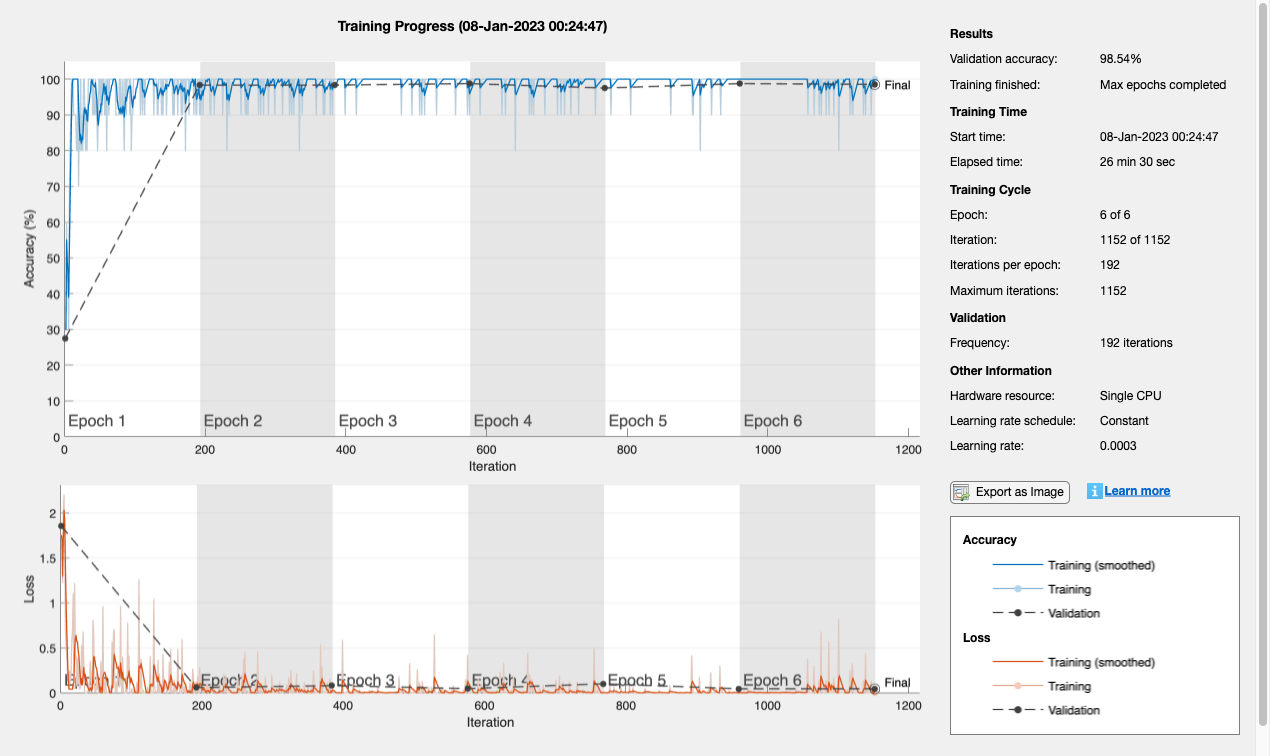

nettrain2 = trainNetwork(augimdsTrain,lgraph2,options);

Save network

save nettrain2

[YPrednet2,scoresnet2] = classify(nettrain2,augimdsValidation);

Display four sample validation images and their labels

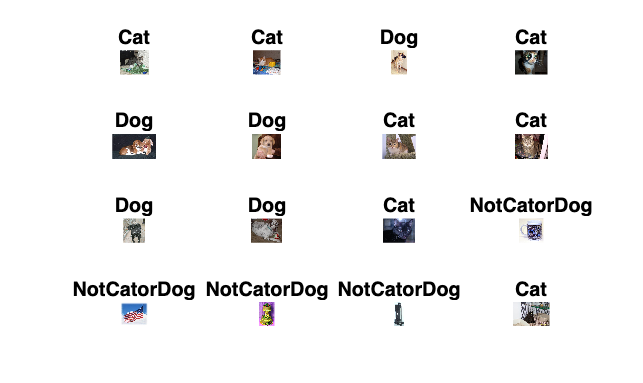

r = randperm(augimdsValidation.NumObservations,16);
for i = 1:numel(r)
    subplot(4,4,i)
    I = readimage(imdsValidation,r(i));
    label2 = YPrednet2(r(i));
    imshow(I)
    title(label2)
end

Calculate accuracy

YValidationnet2= imdsValidation.Labels;
accuracy2 = mean(YPrednet2 == YValidationnet2)

accuracy2 = 0.9854

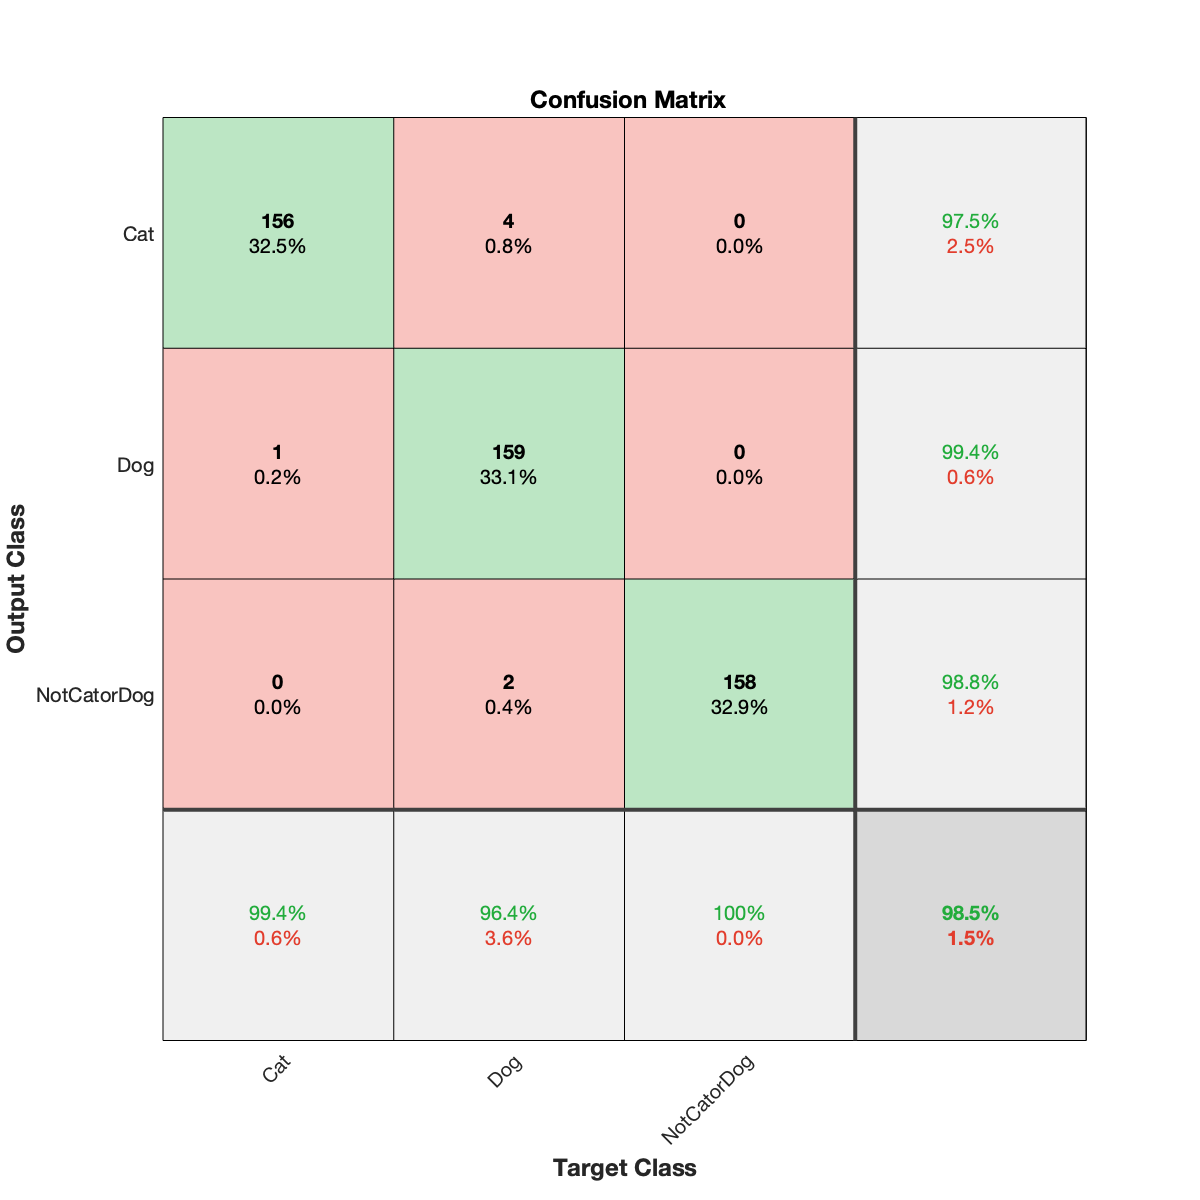

plotconfusion(YPrednet2,YValidationnet2)

### Alexnet

net3=alexnet;
net3.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [227 227 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [227×227×3 single]


% resize image
inputSize2 = net3.Layers(1).InputSize

inputSize2 =    227   227     3


### **Replace Final Layers**

lgraph3 = layerGraph(net3);
[learnableLayer,classLayer] = findLayersToReplace(lgraph3);
[learnableLayer,classLayer]

ans =   1×2 Layer array with layers:

     1   'fc8'      Fully Connected         1000 fully connected layer
     2   'output'   Classification Output   crossentropyex with 'tench' and 999 other classes

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end
lgraph3 = replaceLayer(lgraph3,learnableLayer.Name,newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph3 = replaceLayer(lgraph3,classLayer.Name,newClassLayer);
layers3 = lgraph3.Layers;
connections = lgraph3.Connections;
layers3(1:10) = freezeWeights(layers3(1:10));
lgraph3 = createLgraphUsingConnections(layers3,connections);

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
augimdsTrain2 = augmentedImageDatastore(inputSize2,imdsTrain, ...
    'DataAugmentation', imageAugmenter,'ColorPreprocessing','gray2rgb');
augimdsValidation2 = augmentedImageDatastore(inputSize2,imdsValidation,"ColorPreprocessing","gray2rgb");
miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain2.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation2, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

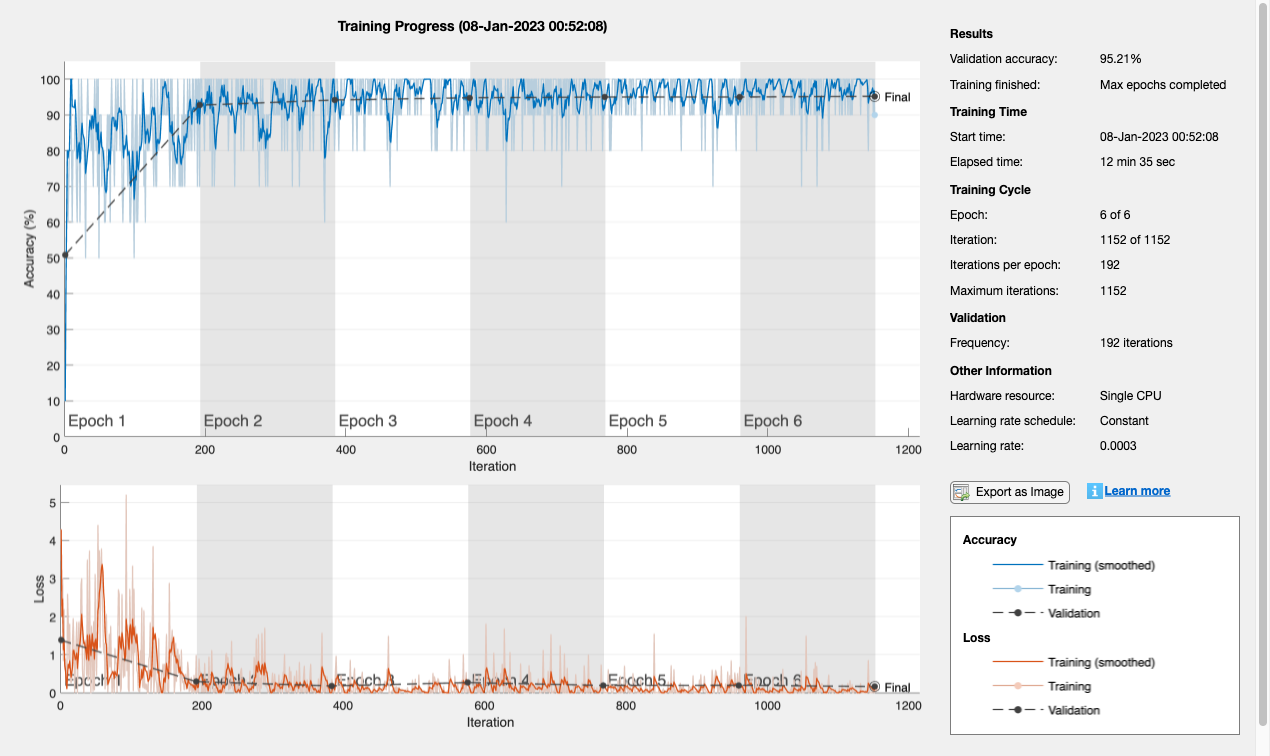

% train alexnet
nettrain3 = trainNetwork(augimdsTrain2,lgraph3,options);

Save network

save nettrain3

Classify test set images

[YPrednet3,scoresnet3] = classify(nettrain3,augimdsValidation2);

Display four sample validation images and their labels

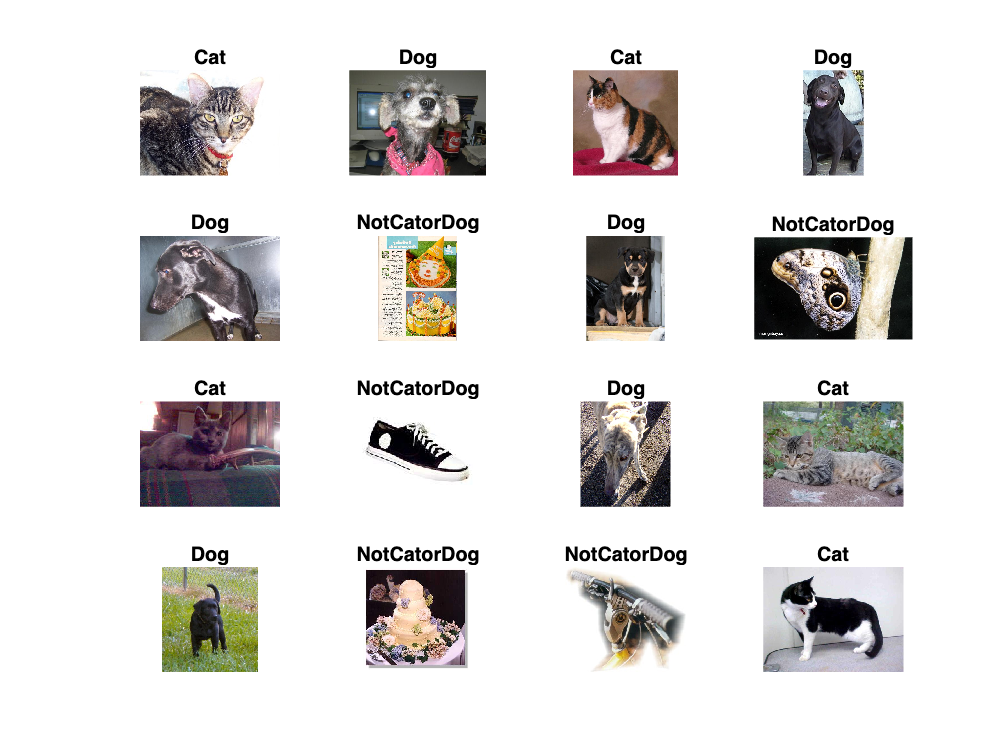

r = randperm(augimdsValidation2.NumObservations,16);
for i = 1:numel(r)
    subplot(4,4,i)
    I = readimage(imdsValidation,r(i));
    label3 = YPrednet3(r(i));
    imshow(I)
    title(label3)
end

Calculate accuracy

YValidationnet3= imdsValidation.Labels;
accuracy3 = mean(YPrednet3 == YValidationnet3)

accuracy3 = 0.9521

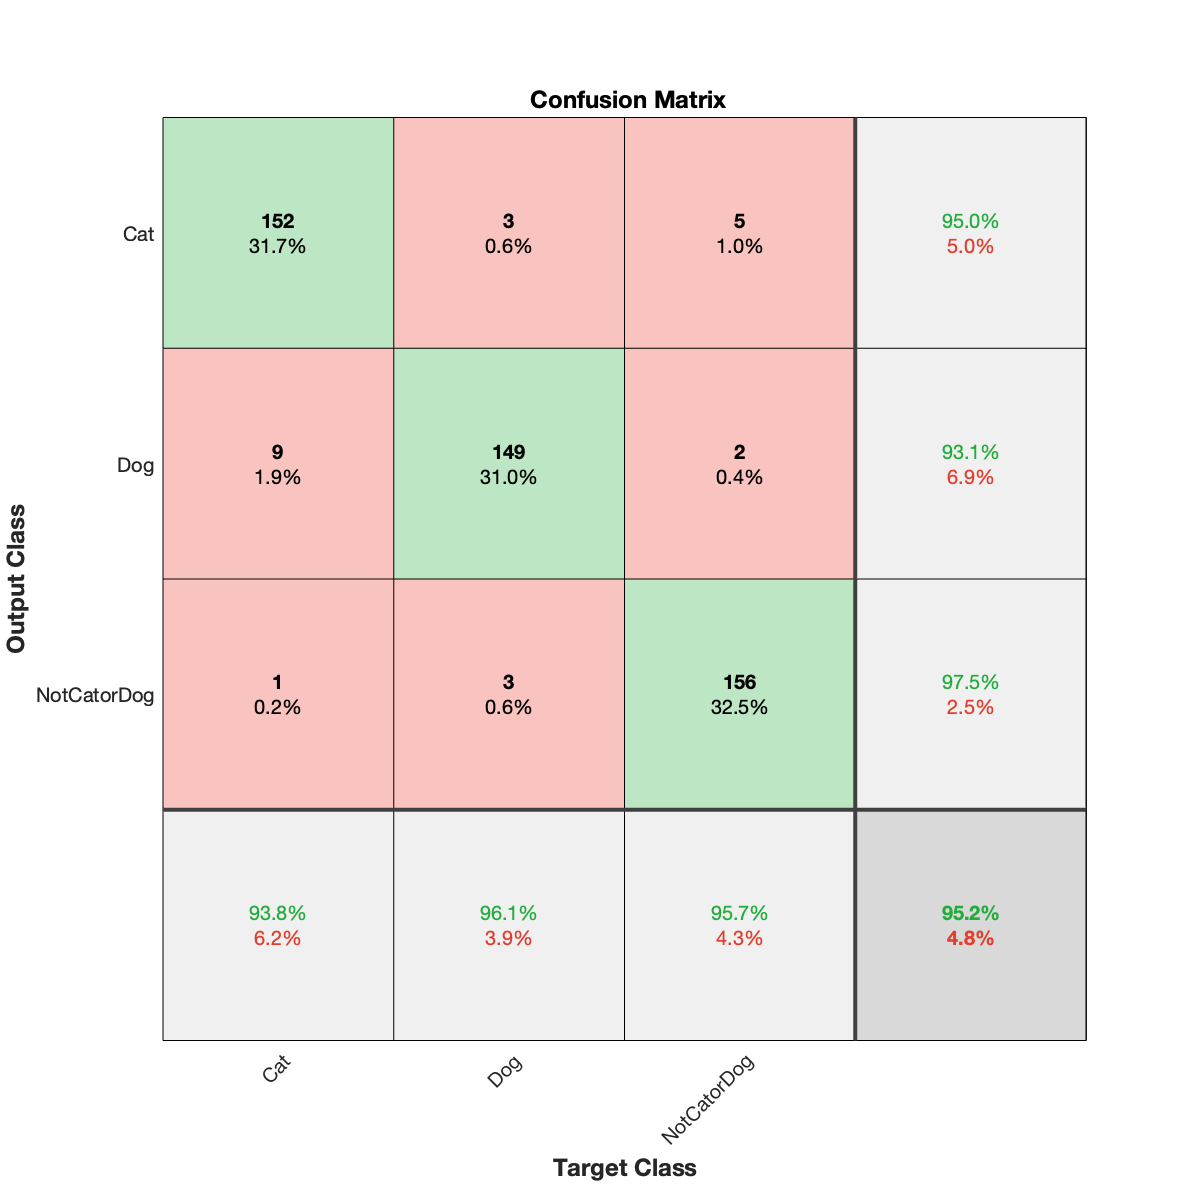

plotconfusion(YPrednet3,YValidationnet3)

private function

function[learnableLayer,classLayer] = findLayersToReplace(lgraph)
if ~isa(lgraph,'nnet.cnn.LayerGraph')
    error('Argument must be a LayerGraph object.')
end
% Get source, destination, and layer names.
src = string(lgraph.Connections.Source);
dst = string(lgraph.Connections.Destination);
layerNames = string({lgraph.Layers.Name}');

% Find the classification layer. The layer graph must have a single
% classification layer.
isClassificationLayer = arrayfun(@(l) ...
    (isa(l,'nnet.cnn.layer.ClassificationOutputLayer')|isa(l,'nnet.layer.ClassificationLayer')), ...
    lgraph.Layers);

if sum(isClassificationLayer) ~= 1
    error('Layer graph must have a single classification layer.')
end
classLayer = lgraph.Layers(isClassificationLayer);


% Traverse the layer graph in reverse starting from the classification
% layer. If the network branches, throw an error.
currentLayerIdx = find(isClassificationLayer);
while true
    
    if numel(currentLayerIdx) ~= 1
        error('Layer graph must have a single learnable layer preceding the classification layer.')
    end
    
    currentLayerType = class(lgraph.Layers(currentLayerIdx));
    isLearnableLayer = ismember(currentLayerType, ...
        ['nnet.cnn.layer.FullyConnectedLayer','nnet.cnn.layer.Convolution2DLayer']);
    
    if isLearnableLayer
        learnableLayer =  lgraph.Layers(currentLayerIdx);
        return
    end
    
    currentDstIdx = find(layerNames(currentLayerIdx) == dst);
    currentLayerIdx = find(src(currentDstIdx) == layerNames);
end
end

function layers = freezeWeights(layers)
% layers = freezeWeights(layers) sets the learning rates of all the
% parameters of the layers in the layer array |layers| to zero.

for ii = 1:size(layers,1)
    props = properties(layers(ii));
    for p = 1:numel(props)
        propName = props{p};
        if ~isempty(regexp(propName, 'LearnRateFactor$', 'once'))
            layers(ii).(propName) = 0;
        end
    end
end
end


function lgraph = createLgraphUsingConnections(layers,connections)
lgraph = layerGraph();
for i = 1:numel(layers)
    lgraph = addLayers(lgraph,layers(i));
end

for c = 1:size(connections,1)
    lgraph = connectLayers(lgraph,connections.Source{c},connections.Destination{c});
end
end